# **Linealización del sistema dinámico de un robot diferencial.**

**Frida Lizett Zavala Pérez A01275226.**

%Variables simbólicas
syms w1 w2 theta x y v_x v_y real
%Parámetros
b=0.5; % separación del centro del eje de tracción a las ruedas
e=1; %separación del punto de control al centro del eje
R=0.25; %radio de la rueda

.

%%Modelo cinemático
v=(w1*R + w2*R)/2;       %velocidad lineal
w=(w2*R -w1*R)/(2*b);    %velocidad angular

.

%%Ecuaciones de movimiento del robot 
dxdt=v*cos(theta);
dydt=v*sin(theta);
dthetadt=w;

.

%%Obtengo la representación de las ecuaciones de estado
estado= [x y theta]'; entradas = [w1 ; w2];
destadodt= [dxdt; dydt; dthetadt];

.

%Las ecuaciones de salida serán la posición 2D del punto descentrado
xp=x+e*cos(theta);
yp=y+e*sin(theta);
EcSalida= [xp;yp]

$$EcSalida = \left(\begin{array}{c} x+\cos\left(\theta \right)\\ y+\sin\left(\theta \right) \end{array}\right)$$

.

%Las derivadas de las salidas respecto al tiempo son:
dsalidadt= jacobian (EcSalida, estado)*destadodt

$$dsalidadt = \left(\begin{array}{c} \cos\left(\theta \right)\,\left(\frac{w_{1}}{8}+\frac{w_{2}}{8}\right)+\sin\left(\theta \right)\,\left(\frac{w_{1}}{4}-\frac{w_{2}}{4}\right)\\ \sin\left(\theta \right)\,\left(\frac{w_{1}}{8}+\frac{w_{2}}{8}\right)-\cos\left(\theta \right)\,\left(\frac{w_{1}}{4}-\frac{w_{2}}{4}\right) \end{array}\right)$$

.

%dsalidadt es una función que devuelve las "velocidades del punto descentrado"
%en función de las velocidades de las ruedas y orientación"
%El objetivo es invertirla para tener una función que devuelva las
%"Velocidades de las ruedas" en función de las "velocidades del punto
% descentrado y su orientación"

%Podemos igualarlas a los valores deseados, e intentar resolver 
%para despejar w1 y w2

sol= solve(dsalidadt==[v_x ; v_y],{w1,w2});

simplify(sol.w1)

$$ans = 4\,v_{x}\,\cos\left(\theta \right)-2\,v_{y}\,\cos\left(\theta \right)+2\,v_{x}\,\sin\left(\theta \right)+4\,v_{y}\,\sin\left(\theta \right)$$

simplify(sol.w2)

$$ans = 4\,v_{x}\,\cos\left(\theta \right)+2\,v_{y}\,\cos\left(\theta \right)-2\,v_{x}\,\sin\left(\theta \right)+4\,v_{y}\,\sin\left(\theta \right)$$

.

global Desacoplador
Desacoplador=matlabFunction([sol.w1;sol.w2]) 

Desacoplador = function_handle with value:
    @(theta,v_x,v_y)[((v_x.*cos(theta).*2.0-v_y.*cos(theta)+v_x.*sin(theta)+v_y.*sin(theta).*2.0).*2.0)./(cos(theta).^2+sin(theta).^2);((v_x.*cos(theta).*2.0+v_y.*cos(theta)-v_x.*sin(theta)+v_y.*sin(theta).*2.0).*2.0)./(cos(theta).^2+sin(theta).^2)]


.

destadodt_bc=simplify(subs(destadodt,{w1,w2},{sol.w1,sol.w2}),50)

$$destadodt\_bc = \left(\begin{array}{c} v_{x}\,{\cos\left(\theta \right)}^{2}+v_{y}\,\sin\left(\theta \right)\,\cos\left(\theta \right)\\ v_{y}\,{\sin\left(\theta \right)}^{2}+\frac{v_{x}\,\sin\left(2\,\theta \right)}{2}\\ v_{y}\,\cos\left(\theta \right)-v_{x}\,\sin\left(\theta \right) \end{array}\right)$$

**Función linealizada en tiempo continuo**

function dx_Lineal_continuo = fcn(x, v, theta)
dx_No_Lineal= v*cos(theta);
dx_Lineal_continuo = -v*sin(theta)*theta
dx_Lineal_discreto = x -v*sin(theta)*theta

**Función no lineal**

function dx_No_Lineal = fcn(x, v, theta)
dx_No_Lineal= v*cos(theta);
dx_Lineal_continuo = -v*sin(theta)*theta
dx_Lineal_discreto = x -v*sin(theta)*theta

V = 1, W =1

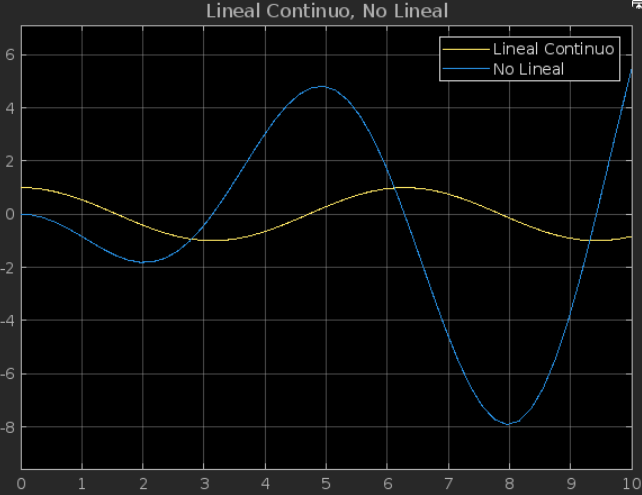

V = 3, W = 3

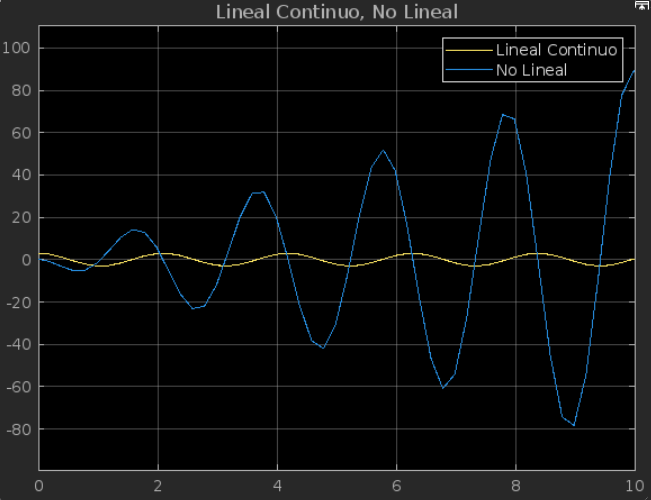

V = 6, W = 6

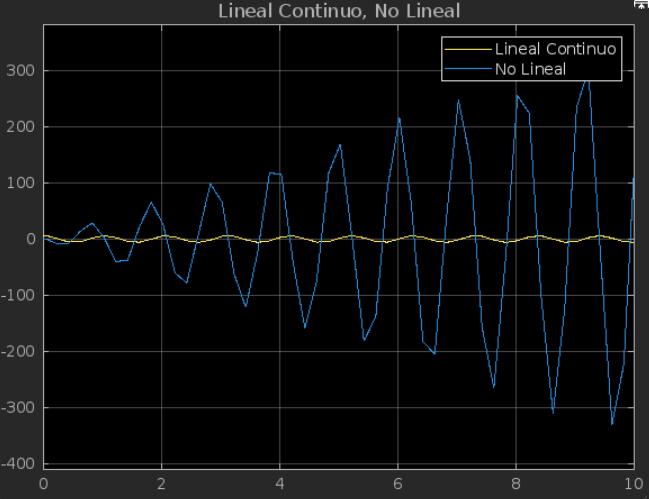

V = 0.5, W = 0.5

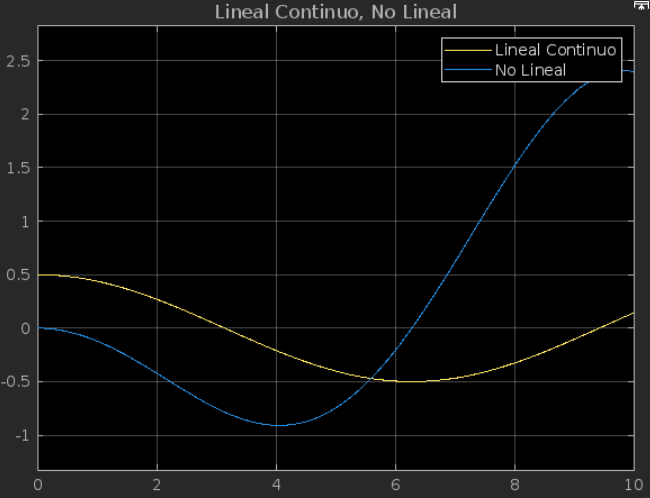

En las respuestas con las velocidades diferentes se ve cómo la velocidad de la función no lineal, muestra más cambios, mientras mayores sean V y W, más se descontrola, es por ello que al linearizarse esta puede contenerse mejor. Esto en el robot hace que al llegar a los puntos de la trayectoria pueda modular mejor la velocidad y aproximarse más. 

La linearización se realiza para simplificar el análisis del sistema no lineal ya que estos pueden ser muy complejos para resolver de manera analítica o matemáticamente. El comportamiento de un sistema líneal se puede aproximar en torno a un punto de equilivrio, en este caso puntos de operación. Una vez linealizado el modelo se le pueden aplicar tecnicas matemáticas ya definidas, igualmente el controlador que se diseñará funciona mejor en sistemas lineales y se puede simular de manera más rapida y eficiente para analizar y evaluar el comportamiento. 